dir = 'Data/Scene_2D_Maps/';
mkdir(dir);

dir_ = "Data/Scene_2D_Maps/Black Canyon of the Gunnison/"

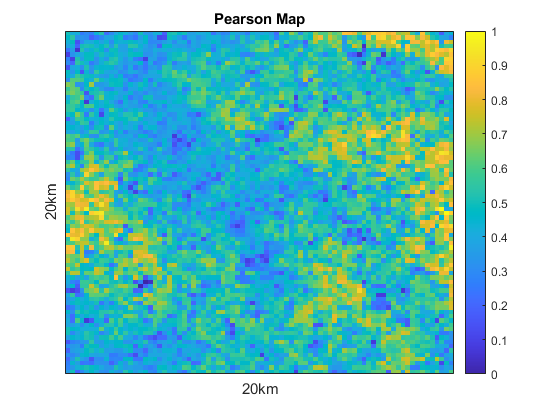

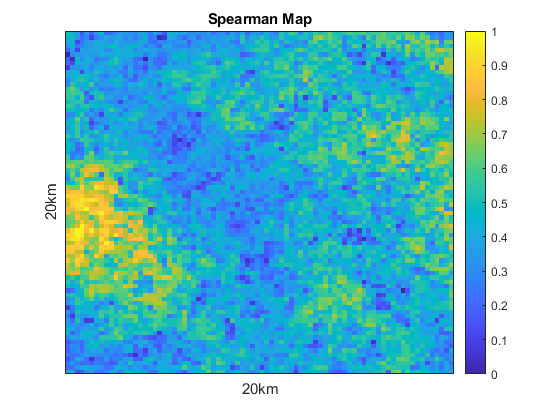

dir_ = "Data/Scene_2D_Maps/Gunnison Point/"

dir_ = "Data/Scene_2D_Maps/Marble Canyon/"

dir_ = "Data/Scene_2D_Maps/Teays Valley/"

dir_ = "Data/Scene_2D_Maps/Oljato Monument Valley/"

dir_ = "Data/Scene_2D_Maps/Sentinel Mesa/"

dir_ = "Data/Scene_2D_Maps/Grand Mesa/"

dir_ = "Data/Scene_2D_Maps/Mt Hood/"

dir_ = "Data/Scene_2D_Maps/Mt Rainier/"

dir_ = "Data/Scene_2D_Maps/Mt St Helens/"


for i = 1:m_scene_count
  dir = 'Data/Scene_2D_Maps/';
  dir_ = append(dir, m_scene_names(i), '/')
  mkdir(dir_);
  tag = '.png';
  
  s = default_scenes(i);
  
  map_type = 'Pearson';
  fpath = append(dir_, map_type, tag);
  fig = pearson_fig(s);
  saveas(fig, fpath, 'png');
  clf;
  
  map_type = 'Spearman';
  fpath = append(dir_, map_type, tag);
  fig = spearman_fig(s);
  saveas(fig, fpath, 'png');
  clf;
  
  map_type = 'MXVI';
  fpath = append(dir_, map_type, tag);
  fig = avg_mxvi_fig(s);
  saveas(fig, fpath, 'png');
  clf;
  
  map_type = 'Elevation';
  fpath = append(dir_, map_type, tag);
  fig = elev_fig(s);
  saveas(fig, fpath, 'png');
  clf;
  
  map_type = 'MXVI_std';
  fpath = append(dir_, map_type, tag);
  
  map_type = 'Elevation_std';
  fpath = append(dir_, map_type, tag);
end